# Ex11. Introduction to Signals and systems

### s1320112/ Motohisa YAMANO

## 1. Generate H(z) IIR Filter and Apply them to the Signal

 This assignment involves designing the IIR filter that I calculated in the Math Problem and applying it to the raw signal x. To facilitate a comparative analysis, the resulting magnitude and phase characteristics, along with the filtered signals, are organized into a 2×3 subplot grid.

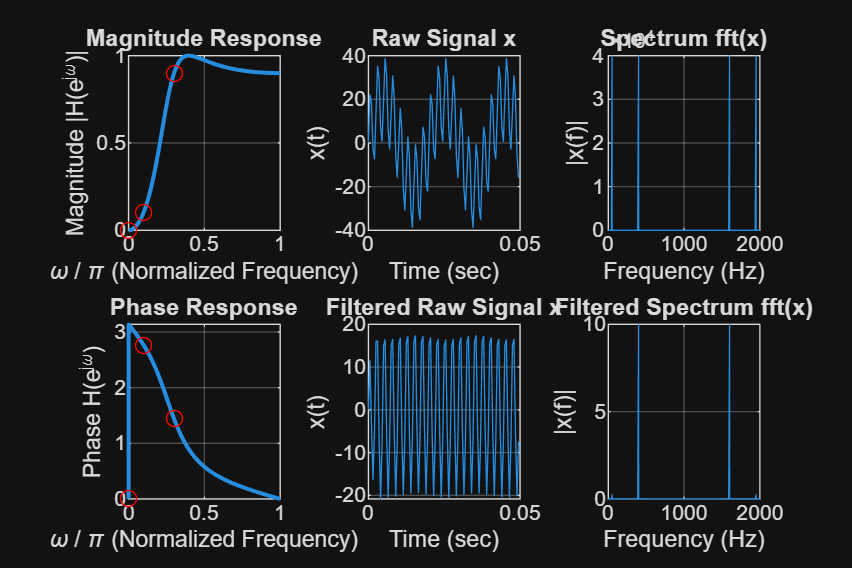

omega_s = 0.1 * pi;
omega_p = 0.3 * pi; 
delta_s = 0.1;       
delta_p = 0.1;

Omega_so = tan(pi/20);
Omega_po = tan(3*pi/20);

Omega_S = 1/Omega_so;
Omega_P = 1/Omega_po;

k = Omega_P/Omega_S;
d = sqrt(19/8019);
epsilon_2 = 19/81;

c4 = 4 * epsilon_2 / (Omega_P^4);
c2 = -4 * epsilon_2 / (Omega_P^2);
c0 = 1 + epsilon_2;
poly_s4 = [c4, 0, -c2, 0, c0];
H2_roots = roots(poly_s4);
lhp_roots = H2_roots(real(H2_roots) < 0);
den_lpf = poly(lhp_roots); 
g0 = 1 / sqrt(1 + epsilon_2);
num_lpf = g0 * den_lpf(3);
num_hpf = [num_lpf, 0, 0];           
den_hpf = [den_lpf(3), den_lpf(2), den_lpf(1)];
[b, a] = bilinear(num_hpf, den_hpf, 0.5);

figure('Position', [100 100 1200 800]);
subplot(2, 3, 1);
[H, w] = freqz(b, a, 2048);
mag = abs(H);
plot(w/pi, mag, 'LineWidth', 1.5);
hold on;
w_test = [0, 0.1*pi, 0.3*pi];
H_test = freqz(b, a, w_test);
mag_test = abs(H_test);
plot(w_test/pi, mag_test, 'ro');
xlabel('\omega / \pi (Normalized Frequency)');
ylabel('Magnitude |H(e^{j\omega})|');
title('Magnitude Response');
grid on;

subplot(2, 3, 4);
pha = phase(H);
plot(w/pi, pha, 'LineWidth', 1.5);
hold on;
plot(w_test/pi, phase(H_test), 'ro');
xlabel('\omega / \pi (Normalized Frequency)');
ylabel('Phase H(e^{j\omega})');
title('Phase Response');
grid on;

show_range = 1:100;
f_axis = (0:L-1)*(F_s/L);
subplot(2, 3, 2);
F_s = 2000;
T = 1/F_s;
L = 2*F_s;
t = (0: L-1)*T;
f1 = 50;
f2 = 400;
x1 = 20.*sin(2*pi*f1.*t);
x2 = 20.*sin(2*pi*f2.*t);
x = x1 + x2;
plot(t(show_range), x(show_range));
xlabel('Time (sec)');
ylabel('x(t)');
title('Raw Signal x');
grid on;

subplot(2, 3, 3);
x_fft = fft(x);
plot(f_axis, abs(x_fft));
xlabel('Frequency (Hz)');
ylabel('|x(f)|');
title('Spectrum fft(x)');
grid on;

subplot(2, 3, 5);
x_filtered = filter(b, a, x);
plot(t(show_range), x_filtered(show_range));
xlabel('Time (sec)');
ylabel('x(t)');
title('Filtered Raw Signal x');
grid on;

subplot(2, 3, 6);
x_filtered_fft = fft(x_filtered);
plot(f_axis, abs(x_filtered_fft)/L);
xlabel('Frequency (Hz)');
ylabel('|x(f)|');
title('Filtered Spectrum fft(x)');
grid on;

## 2. Math Problem

Below is the snapshot of my answer in fill-blank math problem. The values were not calculated by hand; instead, they are the results obtained using MATLAB, rounded to four decimal places. 